clear, close all, clc;

**Two Parts :**

    1. Force Sensor source Data Preview

    2. Force Sensor RMS feature extracted

Everything works like the dEMG-software.

**0. Read Source Data**

force = csvread('ForcePreview-10K.csv', 1, 0);
size(force)

ans =       720000           4


force(1:10, :)

ans =          0    0.7408         0         0
    0.0001    0.7431    0.0001         0
    0.0001    0.7444    0.0001         0
    0.0001    0.7457    0.0001         0
    0.0002    0.7476    0.0002         0
    0.0003    0.7486    0.0003         0
    0.0003    0.7498    0.0003         0
    0.0004    0.7507    0.0004         0
    0.0004    0.7520    0.0004         0
    0.0004    0.7525    0.0004         0


t = force(:, 1);
RawForce = force(:, 2);
FilteredForce = force(:, 4);

Explanation on force-data-structure

[ time-series, force-data, time-series, filted-force]

Fs = 20000; % 20KHz sampling frequency

**1. Raw Force data Displaying...**

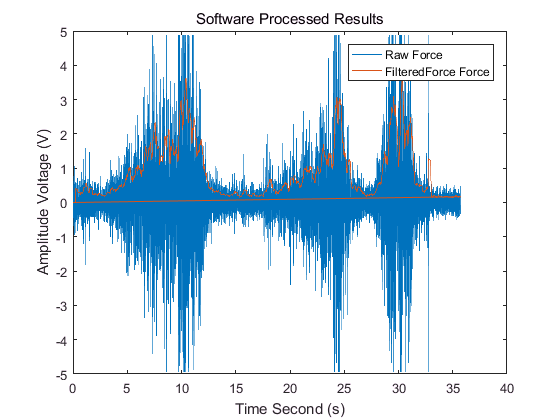

figure('Name', 'Softare Processed Result');
plot(t, RawForce, t, FilteredForce);
legend('Raw Force', 'FilteredForce Force');
xlabel('Time Second (s)');
ylabel('Amplitude Voltage (V)');
title('Software Processed Results');

**2. Self-Processed data Displaying...**

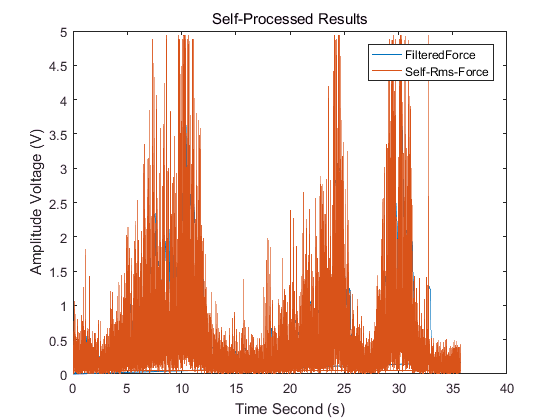

tWL = 0.2; % window length = 0.25 seconds
pWL = tWL * Fs; % points in one window length
nWindows = size(force, 1)/Fs/tWL;
RmsForce = [];
for n = 0:nWindows-1
    Rms = ones(pWL,1) * rms(RawForce(n*pWL+1:n*pWL+pWL));
    RmsForce = [RmsForce; ...
                Rms];
end
figure();
plot(t, FilteredForce, t, RmsForce);
legend('FilteredForce', 'Self-Rms-Force');
xlabel('Time Second (s)');
ylabel('Amplitude Voltage (V)');
title('Self-Processed Results');

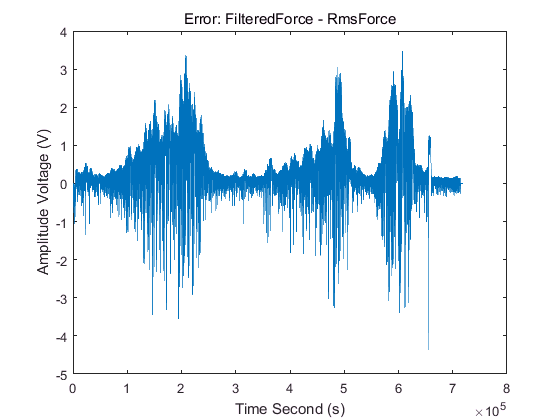

ForceError = FilteredForce - RmsForce;
plot(ForceError);
xlabel('Time Second (s)');
ylabel('Amplitude Voltage (V)');
title('Error: FilteredForce - RmsForce');